load('scans/lidar2.mat', 'lidar_results', 'lidar_positions');
% lidar.mat has a lidar matrix which is n x 2 x m, where each (:, :, m) is
% one scan in the form of [r, theta], where r and theta are column vectors.
% It also has a 3 x m matrix of column vectors of the format [x, y, phi]

generate_potential_field(x, y, [x1, y1; x2, y1])

Unrecognized function or variable 'x'.


clf;

for i=1:size(lidar_results, 3)
    r_G = to_global(lidar_results(:, 1, i), lidar_results(:, 2, i), lidar_positions(i, 1:2), lidar_positions(i, 3));
    
    label = sprintf("(%1.2f, %1.2f, %1.0fdeg)", lidar_positions(i, 1), lidar_positions(i, 2), lidar_positions(i, 3));
        
    plot(r_G(:, 1), r_G(:, 2), '.', 'DisplayName', label); hold on;
end

legend show;
title("The Final Gauntlet");
xlabel("X Distance (m)");
ylabel("Y Distance (m)");
xlim([-1.5, 3]);
ylim([-3.5, 1]);

axis equal;

hold off;

## Potential Field

% [X, Y] = meshgrid(linspace(-5, 5), linspace(-5, 5));

syms X Y

wall_lines = [
    -1.5, -3.37, -1.5,     1;
     2.5, -3.37,  2.5,     1;
     2.5, -3.37, -1.5, -3.37;
     2.5,     1, -1.5,      1 
];

obstacle_info = [   -0.25, -1.0, pi/4, 0.5;
                     1.41, -2.0,    0, 0.5;
                     1.00, -0.7, pi/4, 0.5];

obstacle_lines = [];

for i=1:size(obstacle_info, 1)
    obstacle_lines = [obstacle_lines; squareToLines(obstacle_info(i, 1), obstacle_info(i, 2), obstacle_info(i, 3), obstacle_info(i, 4))];
end

Z = + generatePotentialLines(X, Y, obstacle_lines) ...
    - 1.5 * generatePotentialLines(X, Y, wall_lines) ...
    - 4 * generatePotentialCircle(X, Y, [.75, -2.5], .25);
f = matlabFunction(Z);

figure; clf;
fsurf(f, [-4, 3]); xlim([-2, 3]); ylim([-3.75, 1.5]); xlabel("X"); ylabel("Y"); zlabel("Z");

figure; clf;

fcontour(f); hold on;

all_lines = [wall_lines; obstacle_lines];

for i=1:size(all_lines, 1)
    plot([all_lines(i, 1), all_lines(i, 3)], [all_lines(i, 2), all_lines(i, 4)], 'k-');
end

## Gradient Ascent

grad = matlabFunction(gradient(Z));
[positions, headings] = gradient_ascent(grad, [0, 0], [1, 0], .0001, 1.1, .001, 1000)

positions =          0         0
   -0.0014    0.0032
   -0.0027    0.0064
   -0.0041    0.0095
   -0.0054    0.0127
   -0.0068    0.0159
   -0.0081    0.0190
   -0.0095    0.0222
   -0.0108    0.0254
   -0.0121    0.0285


headings =     1.0000         0
   -0.3932    0.9195
   -0.3929    0.9196
   -0.3926    0.9197
   -0.3922    0.9199
   -0.3919    0.9200
   -0.3916    0.9202
   -0.3912    0.9203
   -0.3908    0.9205
   -0.3904    0.9206


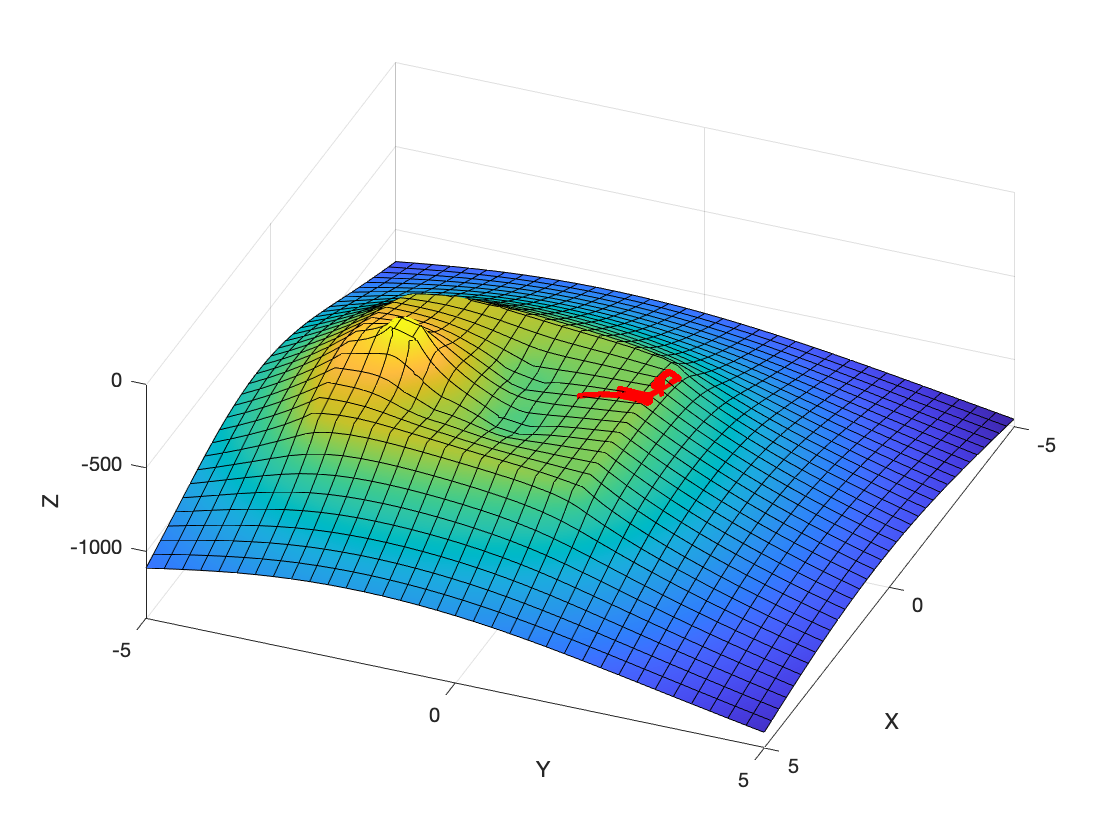

figure; clf;
fsurf(f, [-5, 5]); hold on;
plot3(positions(:, 1), positions(:, 2), f(positions(:, 1), positions(:, 2)), 'r.-', 'LineWidth', 3, "MarkerSize", 10)
xlim([-5, 5]); ylim([-5, 5]); xlabel("X"); ylabel("Y"); zlabel("Z"); zlim([-1400, 0])

view([112 56]);

function r_G = to_global(R, theta, origin, phi)
    [X_raw, Y_raw] = pol2cart(theta,  R);
    r_L = [X_raw, Y_raw, ones(length(X_raw), 1)]';
    r_N = [1, 0, 0.084; 0, 1, 0; 0, 0, 1] * r_L; % no rotation needed
    r_G_raw = [1, 0, origin(1); 0, 1, origin(2); 0, 0, 1] * [cos(phi), -sin(phi), 0; sin(phi), cos(phi), 0; 0, 0, 1] * r_N;
    r_G = r_G_raw(1:2, :)';
end

function r_G = plot_helper(position, results, desc)
    if nargin < 3
        desc = "Neato's View";
    end
    
    % old params: R, theta, origin, phi, desc


end